% Step 1: Define Constants and Inputs
fuel_flow_rate_scfm = 50; % Fuel flow rate in standard cubic feet per minute (SCFM)
fuel_flow_rate = fuel_flow_rate_scfm * 0.0283168; % Convert SCFM to m^3/s (standard cubic feet per minute to cubic meters per second)
T_in = 0 + 1000; % Incoming temperature in Kelvin (0°C)
P_in = 101325; % Atmospheric pressure in Pascals (1 atm = 101325 Pa)

% Step 2: Initialize Cantera Object for Fuel-Air Mixture
% Load the GRI 3.0 mechanism (make sure the cti file is in the MATLAB path)
gas = Solution('gri30.yaml'); % This loads the GRI-Mech 3.0 mechanism

iCH4 = speciesIndex(gas,'CH4'); %indices of species of interest
iC2H6 = speciesIndex(gas, 'C2H6');
iO2  = speciesIndex(gas,'O2');
iN2  = speciesIndex(gas,'N2');
iNO = speciesIndex(gas,'NO');
iOH = speciesIndex(gas, 'OH');

x = zeros(nSpecies(gas),1);
x(iCH4,1) = 1; %set equivalence ratio of initial gas mixture
x(iC2H6,1) = 1;
x(iO2,1) = 7;
x(iN2,1) = 3.76*7;
% x(iOH,1) = 0.1;

% Set the gas composition (CH4, C2H6 mixture) and conditions (T, P)
setTemperature(gas, T_in); % Set the temperature of the gas
setPressure(gas, P_in); % Set the pressure of the gas
setMoleFractions(gas, x); % Set the mole fractions of CH4 and C2H6

% Step 3: Calculate Residence Time and Reactor Volume
% Assumption: The destruction efficiency is 99%
destruction_efficiency = 0.99;
mass_flow_rate = fuel_flow_rate * density(gas); % Mass flow rate in kg/s
residence_time = 10; % Assume a residence time in seconds (this value can be modified based on simulation)

% Step 4: Calculate NOx Concentration for Equivalence Ratio
% NOx limit is 5 ppm on a dry basis with 15% O2
NOx_limit = 5e-6; % 5 ppm in dry basis
equivalence_ratio = 1.1; % Starting equivalence ratio (you will modify this to meet the NOx limit)
CH4_concentration = moleFraction(gas, 'CH4')

CH4_concentration = 0.0283

C2H6_concentration = moleFraction(gas, 'C2H6')

C2H6_concentration = 0.0283

NOx_concentration = moleFraction(gas, 'NO')

NOx_concentration = 0


% Set the equivalence ratio and perform equilibrium calculation
% setEquivalenceRatio(gas, equivalence_ratio); % Set the equivalence ratio
equilibrate(gas, 'HP'); % Perform equilibrium calculation at constant enthalpy and pressure

% Get the NOx concentration in the equilibrium mixture
NOx_concentration = moleFraction(gas, 'NO'); % This will give the NOx concentration (ppm)
CH4_concentration = moleFraction(gas, 'CH4')

CH4_concentration = 7.6488e-19

C2H6_concentration = moleFraction(gas, 'C2H6')

C2H6_concentration = 2.8842e-36

% Output the NOx concentration
if NOx_concentration<NOx_limit
    fprintf('NOx Concentration Satisfied: %.2e ppm\n', NOx_concentration);
else
    fprintf('NOx Concentration Not Satisfied: %.2e ppm\n', NOx_concentration);  
end

NOx Concentration Not Satisfied: 7.19e-03 ppm



% Step 5: Calculate Combustion Air Flow Rate Based on Equivalence Ratio
% Use the stoichiometric air-fuel ratio (approx. 17.2 for methane)
stoich_air_fuel_ratio = 17.1; % Stoichiometric air-fuel ratio for methane+ethane (adjust as needed)

% Calculate the actual air-fuel ratio based on equivalence ratio
actual_air_fuel_ratio = equivalence_ratio * stoich_air_fuel_ratio;
air_flow_rate = fuel_flow_rate * actual_air_fuel_ratio; % m^3/s

fprintf('Required Combustion Air Flow Rate: %.2f m^3/s\n', air_flow_rate);

Required Combustion Air Flow Rate: 26.63 m^3/s



% Step 6: Calculate Nozzle Diameter for Laminar Flow
% Reynolds number formula: Re = (rho * v * D) / mu
Re_max = 2000; % Maximum Reynolds number for laminar flow

% Get gas properties (density and viscosity) at the given conditions
rho = density(gas); % Gas density in kg/m^3
mu = viscosity(gas); % Dynamic viscosity in Pa·s

% Calculate the velocity based on fuel flow rate and nozzle diameter
nozzle_diameter = sqrt(4 * fuel_flow_rate / (pi * Re_max)); % Nozzle diameter to maintain Re < 2000

fprintf('Calculated Nozzle Diameter: %.4f meters\n', nozzle_diameter);

Calculated Nozzle Diameter: 0.0300 meters



% Step 7: Design of the Confining Tube
tube_id = 2 * nozzle_diameter; % ID of confining tube should be at least 2x nozzle diameter
tube_thickness = 0.003175; % Wall thickness in meters (1/8 inch)
tube_od = tube_id + 2 * tube_thickness; % Outer diameter of the tube

Nozzle_D = Re_max*mu/(rho*fuel_flow_rate)

Nozzle_D = 10.1099


fprintf('Confining Tube ID: %.4f meters\n', tube_id);

Confining Tube ID: 0.0600 meters


fprintf('Confining Tube OD: %.4f meters\n', tube_od);

Confining Tube OD: 0.0664 meters


## Reactor

nPhis = 25; %number of equivalence ratios to evaluate
phi = linspace(0.3,1.9,nPhis);

for i = 1:1:nPhis
gas = Solution('gri30.yaml');
x = zeros(nSpecies(gas),1);
set(gas,'Temperature',T_in,'Pressure',P_in);%set initial temperature and pressure of gas
x(iCH4,1) = phi(i)/2; %set equivalence ratio of initial gas mixture
x(iC2H6,1) = phi(i)/2;
x(iO2,1) = 1;
x(iN2,1) = 3.76;
% x(iOH,1) = 0.1;
setMoleFractions(gas, x); 

r = Reactor(gas);
% create a reservoir to represent the environment
a = Solution('air.yaml','air','none');
set(a,'P',P_in)
env = Reservoir(a);
% Define a wall between the reactor and the environment and
% make it flexible, so that the pressure in the reactor is held
% at the environment pressure.
w = Wall;
install(w,r,env);

% mfc = MassFlowController(Q_fuel);
% set expansion parameter. dV/dt = KA(P_1 - P_2)
setExpansionRateCoeff(w, 1.0e6);

% set wall area
setArea(w, 1.0);

network = ReactorNet({r});
% create a reservoir to represent the environment
a = Solution('air.yaml','air','none');
set(a,'P',P_in)
env = Reservoir(a);

nSteps = 2000;
tim(nSteps) = 0;
temp(nSteps) = 0;
x(nSteps,3) = 0;
t = 0.0;
dt = 1.0e-6;
t0 = cputime;

for n = 1:nSteps
  t = t + dt;
  advance(network, t);
  tim(n) = time(network);
  temp(n) = temperature(r);
  x(n,1:7) = moleFraction(gas,{'CH4','C2H6','N','NO', 'OH', 'NO2', 'O2'});
end
ReactorMaxT(i) = max(temp(n));

CH4Concentration(i) = max(x(:,1));
C2H6Concentration(i) = max(x(:,2));
NConcentration(i) = max(x(:,3));
NOConcentration(i) = max(x(:,4));
OHConcentration(i) = max(x(:,5));
NO2Concentration(i) = max(x(:,6));
O2Concentration(i) = max(x(:,7));
O2Percent(i) = O2Concentration(i)/CH4Concentration(i)+C2H6Concentration(i)+...
    NConcentration(i)+NOConcentration(i)+OHConcentration(i)+NO2Concentration(i);
end

% Get the NOx concentration in the reactor mixture
NOxConcentration = NOConcentration+NO2Concentration;
NOxConcentration_15O2 = ((NOConcentration+NO2Concentration).*(20.9-15))./(20.9-O2Percent)

NOxConcentration_15O2 =     0.0049    0.0040    0.0028    0.0017    0.0008    0.0004    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% NOx_concentration = moleFraction(gas, 'NO'); % This will give the NOx concentration (ppm)
% CH4_concentration = moleFraction(gas, 'CH4')
% C2H6_concentration = moleFraction(gas, 'C2H6')
% Output the NOx concentration
if NOxConcentration<NOx_limit

NOx Concentration Not Satisfied: 1.18e-02 ppm
NOx Concentration Not Satisfied: 1.05e-02 ppm
NOx Concentration Not Satisfied: 7.68e-03 ppm
NOx Concentration Not Satisfied: 4.76e-03 ppm
NOx Concentration Not Satisfied: 2.45e-03 ppm
NOx Concentration Not Satisfied: 1.07e-03 ppm
NOx Concentration Not Satisfied: 5.32e-04 ppm
NOx Concentration Not Satisfied: 4.80e-04 ppm
NOx Concentration Not Satisfied: 4.27e-04 ppm
NOx Concentration Not Satisfied: 3.21e-04 ppm
NOx Concentration Not Satisfied: 1.25e-04 ppm
NOx Concentration Not Satisfied: 4.36e-05 ppm
NOx Concentration Not Satisfied: 1.72e-05 ppm
NOx Concentration Not Satisfied: 6.44e-06 ppm
NOx Concentration Not Satisfied: 2.11e-06 ppm
NOx Concentration Not Satisfied: 6.92e-07 ppm
NOx Concentration Not Satisfied: 2.94e-07 ppm
NOx Concentration Not Satisfied: 1.88e-07 ppm
NOx Concentration Not Satisfied: 1.27e-07 ppm
NOx Concentration Not Satisfied: 8.88e-08 ppm
NOx Concentration Not Satisfied: 6.42e-08 ppm
NOx Concentration Not Satisfied: 4

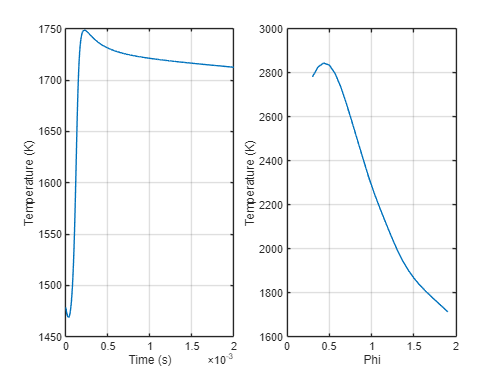

    fprintf('NOx Concentration Satisfied: %.2e ppm\n', NOxConcentration);
else
    fprintf('NOx Concentration Not Satisfied: %.2e ppm\n', NOxConcentration);  
end

figure(1)
subplot(1,2,1);
plot(tim,temp);
xlabel('Time (s)');
ylabel('Temperature (K)');
grid on
subplot(1,2,2)
plot(phi,ReactorMaxT);
xlabel('Phi');
ylabel('Temperature (K)');
grid on

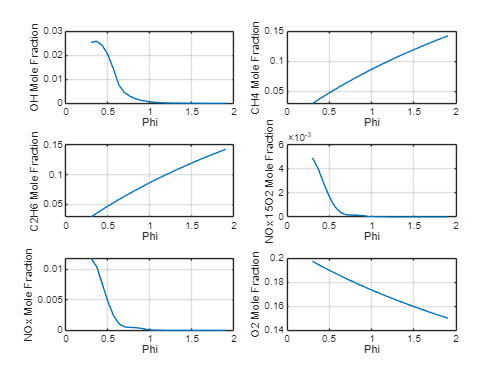


figure(2)
subplot(3,2,1);
plot(phi,OHConcentration);
xlabel('Phi');
ylabel('OH Mole Fraction');
grid on
subplot(3,2,2)
plot(phi,CH4Concentration);
xlabel('Phi');
ylabel('CH4 Mole Fraction');
grid on
subplot(3,2,3)
plot(phi,C2H6Concentration);
xlabel('Phi');
ylabel('C2H6 Mole Fraction');
grid on
subplot(3,2,4)
plot(phi, NOxConcentration_15O2);
xlabel('Phi');
ylabel('NOx 15O2 Mole Fraction');
grid on
subplot(3,2,5)
plot(phi, NOxConcentration);
xlabel('Phi');
ylabel('NOx Mole Fraction');
grid on
subplot(3,2,6)
plot(phi, O2Concentration);
xlabel('Phi');
ylabel('O2 Mole Fraction');
grid on

## Premixed Flame